G(jw)

syms w G0(s) real

G0(s)= 2/(s-1)/(0.5*s+1)

$$G0(s) = \frac{2}{\left(\frac{s}{2}+1\right)\,\left(s-1\right)}$$

jw=1i*w;
A=abs(G0(jw))

$$A = \frac{2}{\sqrt{w^{2}+1}\,\sqrt{\frac{w^{2}}{4}+1}}$$

Phi=angle(G0(jw))

$$Phi = \text{angle}\left(\frac{1}{\left(-1+w\,\mathrm{i}\right)\,\left(1+\frac{w\,\mathrm{i}}{2}\right)}\right)$$


P=simplify(real(G0(jw)));
[num, den]=numden(simplify(real(G0(jw))));
n=sym2poly(num);
d=sym2poly(den);
P=zpk(tf(n,d))

P =
 
     -4 (s^2 + 2)
  -------------------
  (s^2 + 1) (s^2 + 4)
 
Continuous-time zero/pole/gain model.



wP=0;
valP=evalfr(P,wP)

valP = -2.0000


Q=simplify(imag(G0(jw)));
[num, den]=numden(simplify(imag(G0(jw))));
n=sym2poly(num);
d=sym2poly(den);
Q=zpk(tf(n,d))

Q =
 
         -4 s
  -------------------
  (s^2 + 1) (s^2 + 4)
 
Continuous-time zero/pole/gain model.



wQ=wP;
valQ=evalfr(Q,wQ)

valQ = 0


s=tf('s');
G0=2/(s-1)/(0.5*s+1)

G0 =
 
           2
  -------------------
  0.5 s^2 + 0.5 s - 1
 
Continuous-time transfer function.



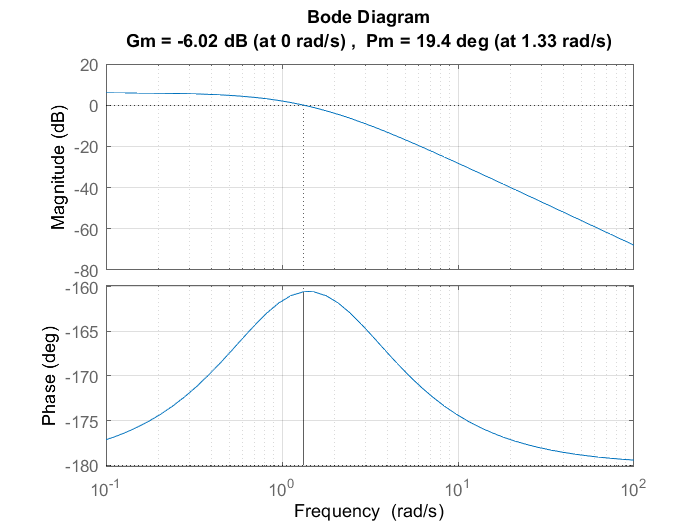

margin(G0);
grid on;

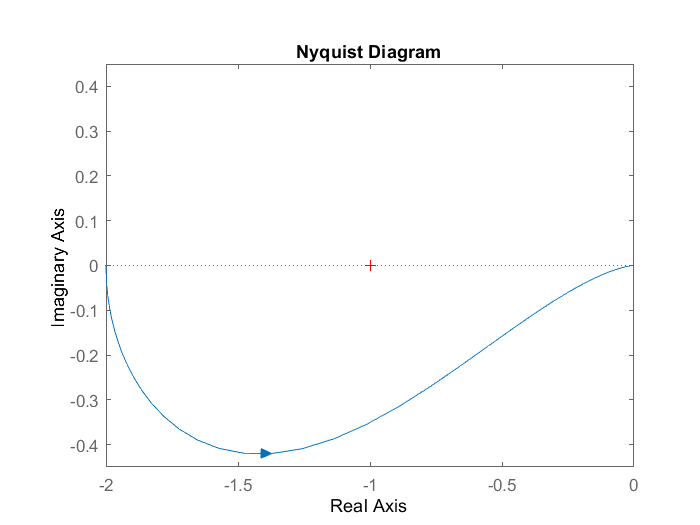


figure
P=nyquistplot(G0);
%xlim([-100,1])
%ylim([-20,20])
setoptions(P,'ShowFullContour','off')

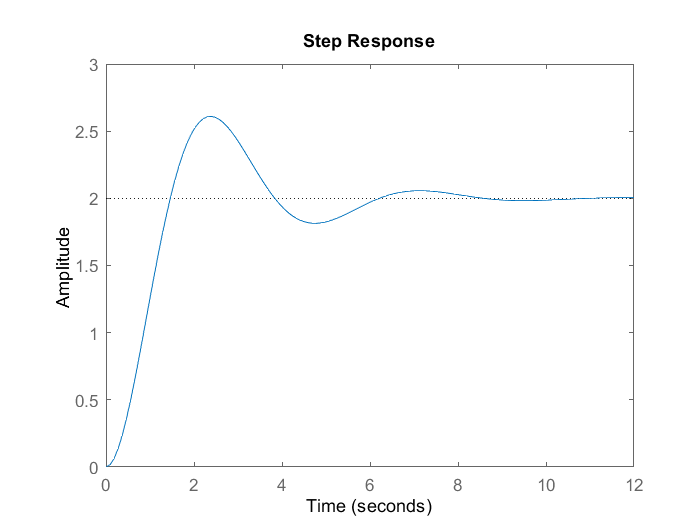

step(feedback(G0,1))